# Part 2: Training an Autoencoder

***Industrial Machinery Anomaly Detection***

# 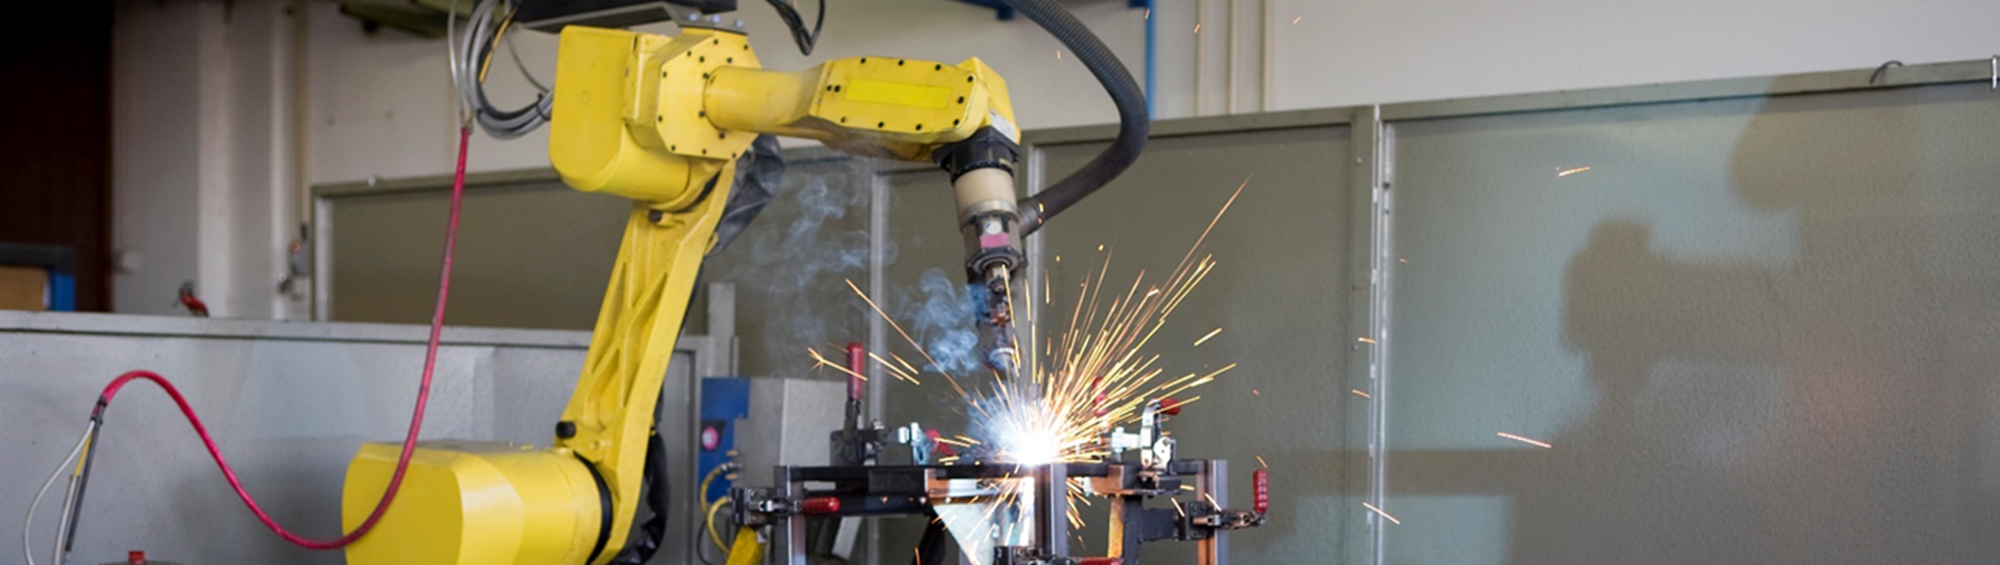

Autoencoders can be used to detect anomalies, and various approaches are available. In this example, we train a bidirectional LSTM autoencoder to detect if a machine is working normally. An autoencoder is trained on a set of 12 features, extracted from healthy operating data collected from vibration sensors directly after a scheduled maintenance period. Features were computed from raw data using the [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) from the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html)™.

We then use the trained model to reconstruct the features extracted from new data. If the model reconstructs the features well, it indicates that the machine is operating normally. If the reconstruction surpasses an error threshold, this indicates that the machine is acting abnormally and requires maintenance.

## **Load Features and Labels**

In the previous section, we extracted highly ranked features from our data. The dataset we looked at previously was actually only a small subset of a much larger dataset that is not included in this example. It is always a good idea to train your algorithm on as much data as possible. 

Here, we will load in the 12 features that were previously extracted from the larger dataset of 17,642 signals.

load("FeatureEntire.mat")
head(featureAll)

ans = 8×13 table
    label     ch1_stats/Col1_CrestFactor    ch1_stats/Col1_Kurtosis    ch1_stats/Col1_RMS    ch1_stats/Col1_Std    ch2_stats/Col1_Mean    ch2_stats/Col1_RMS    ch2_stats/Col1_Skewness    ch2_stats/Col1_Std    ch3_stats/Col1_CrestFactor    ch3_stats/Col1_SINAD    ch3_stats/Col1_SNR    ch3_stats/Col1_THD
    ______    __________________________    _______________________    __________________    __________________    ___________________    __________________    _______________________    __________________    __________________________    ____________________    

The data has two labeled states: Before & After. These refer to data collected before and after maintenance. We will assume that the data collected after maintenance represents a normal (healthy) operating state. We may not be able to say the same for the before data -- because we were performing scheduled maintenance, this data may be either normal or abnormal. 

## **Split into Training and Test Datasets**

We will automatically partition the data into a training set to train the autoencoder, and an independent test set to test the performance. [`cvpartition`](https://www.mathworks.com/help/releases/R2021a/stats/cvpartition.html) does the partitioning for us automatically. 

rng(0) % set for reproducibility

idx = cvpartition(featureAll.label, 'holdout', 0.1);
featureTrain = featureAll(idx.training, :);
featureTest = featureAll(idx.test, :);

## Set up biLSTM Autoencoder Network

We want to extract only the "After" (known healthy) data to train a biLSTM autoencoder and convert to a cell array for processing. When something that doesn't look like healthy data is passed into the autoencoder, it will have a harder time reconstructing the signal -- which will indicate an anomaly.

X = extractLabeledData(featureTrain, ...
    "Label", "After");

Then, construct the biLSTM autoencoder network and set the training options.

featureDimension = 1;

% Define biLSTM network layers
layers = [ sequenceInputLayer(featureDimension, 'Name', 'in')
    bilstmLayer(16, 'Name', 'bilstm1')
    reluLayer('Name', 'relu1')
    bilstmLayer(32, 'Name', 'bilstm2')
    reluLayer('Name', 'relu2')
    bilstmLayer(16, 'Name', 'bilstm3')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(featureDimension, 'Name', 'fc')
    regressionLayer('Name', 'out') ];

% Set Training Options
options = trainingOptions('adam', ...
    'Plots', 'training-progress', ...
    'MiniBatchSize', 500,...
    'MaxEpochs',500);

## Train Network

Now we're ready to train the model. You can load the model that has already been trained, or uncomment line 35 below if you would like to train the network from scratch (this may take a long time depending on your compute resources). 

%net = trainNetwork(X, X, layers, options);
load TrainedNetwork.mat

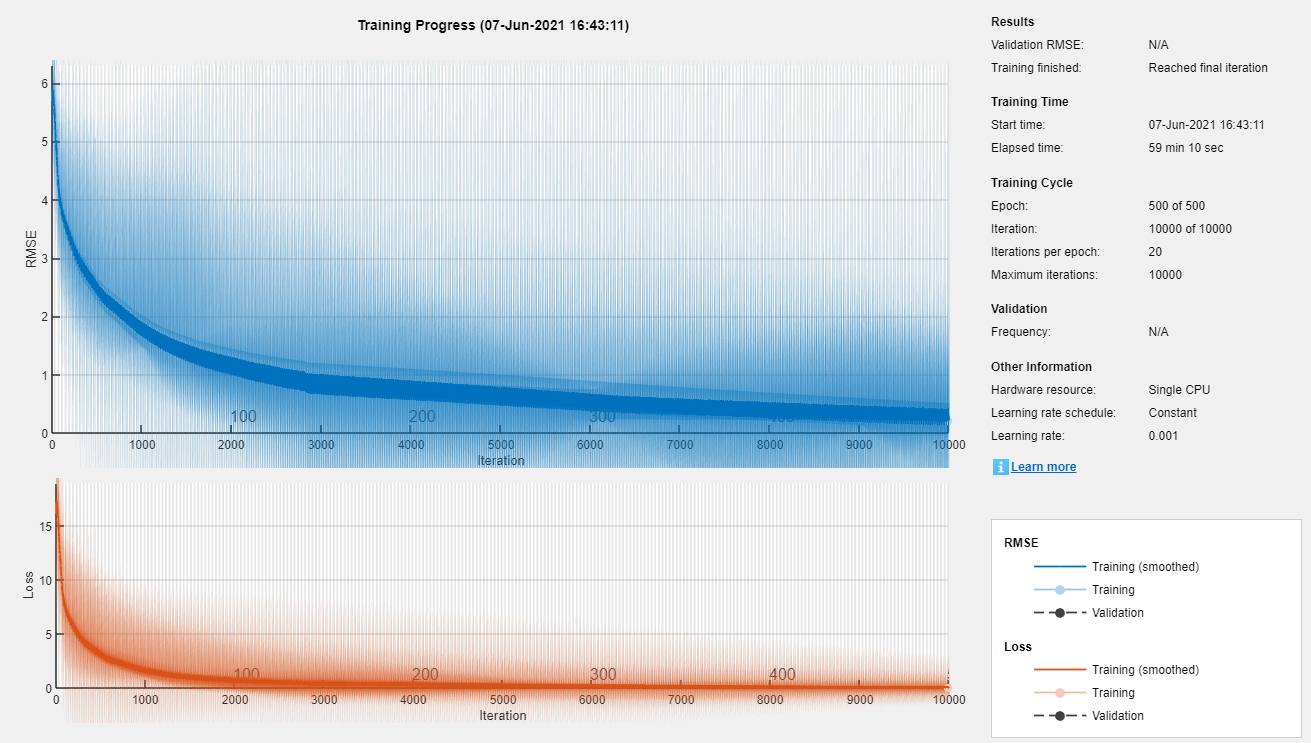

## **Visualize Model Behavior on Validation Data**

Extract and visualize a sample from Before and After maintenance. Note that the plots below are comparing the error in the values of each of the 12 features (indicated on the x-axis). We can see that in this particular sample, features 10-12 do not reconstruct well for the abnormal input and thus have a high error value. This could be an indication that there is an anomaly.

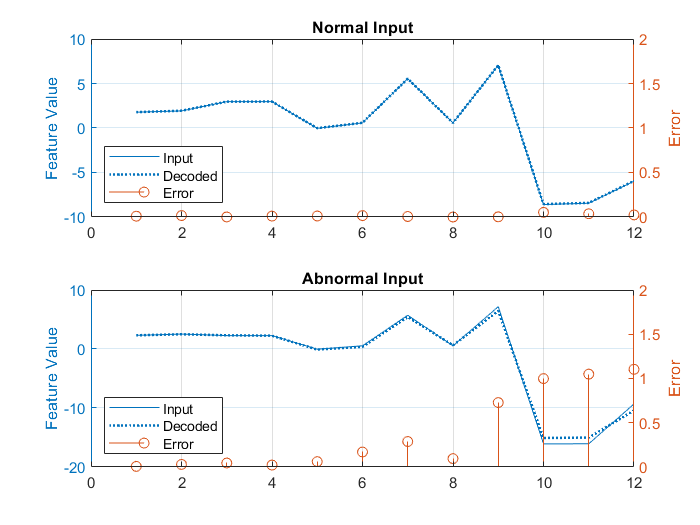

testAfter = {featureTest(1200, 2:end).Variables}; % 1200 is a sample from After
testBefore = {featureTest(200, 2:end).Variables}; % 200 is a sample from Before

% Predict decoded signal for both
decodedAfter = predict(net,testAfter);
decodedBefore = predict(net,testBefore);

% Visualize
visualizeModelBehavior(testAfter, testBefore, decodedAfter, decodedBefore)

## **Visualize Model Error on Validation Data**

Extract data **Before** and **After **maintenance. We can see in the figure that the reconstruction error for the data before maintenance is significantly higher than the data after maintenance. This makes sense, since the autoencoder was trained on the data before maintenance, so it will better reconstruct similar signals. 

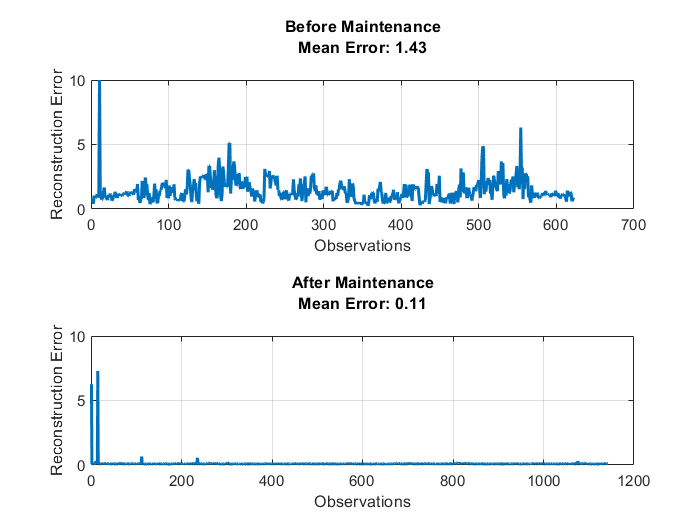

% Extract data Before maintenance
XTestBefore = extractLabeledData(featureTest, ...
    "Label", "Before");

% Predict output before maintenance and calculate error
yHatBefore = predict(net, XTestBefore);
errorBefore = calculateError(XTestBefore, yHatBefore);

% Extract data after maintenance
XTestAfter = extractLabeledData(featureTest, ...
    "Label", "After");

% Predict output after maintenance and calculate error
yHatAfter = predict(net, XTestAfter);
errorAfter = calculateError(XTestAfter, yHatAfter);

visualizeError(errorBefore, errorAfter);

## **Identify Anomalies**

Calculate error on full validation data. 

XTestAll = extractLabeledData(featureTest, ...
    "Label", "All");

yHatAll = predict(net, XTestAll);
errorAll = calculateError(XTestAll, yHatAll);

Define an anomaly as a point which has reconstruction error 0.5 times larger than the mean across all observations. This threshold was determined through a tuning process, which you can adjust using the slider below. 

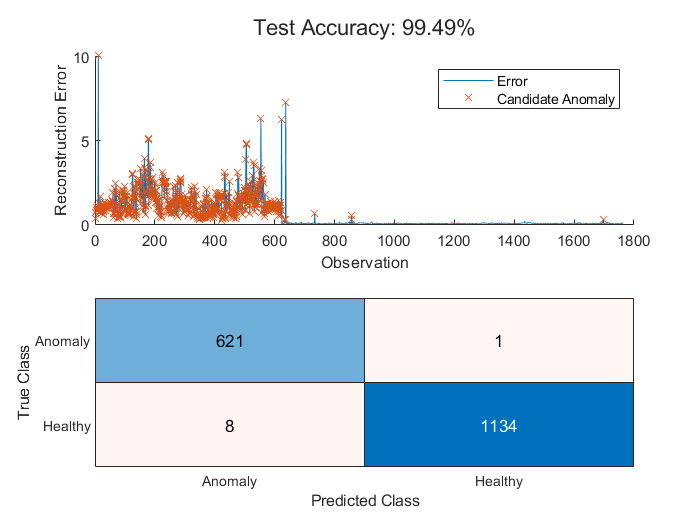

thresh = 0.5;
anomalies = errorAll > thresh*mean(errorAll);

visualizeAnomalies(anomalies, errorAll, featureTest);

## **Summary**

To recap, we started with timeseries signals from a three-axis accelerometer taken from an industrial machine before and after maintenance. We started by extracting the top ranked features from this data to train a deep learning autoencoder to reconstruct the features from healthy data. We then created a threshold that could automate the process of determining if a signal is an anomaly (needs maintenance) based on how well the autoencoder reconstructed the features. 

As an alternative to the biLSTM used in this example, you could train an autoencoder using few fully connected layers. Learn more about other types of autoencoders with these examples: [Variational Autoencoder](https://www.mathworks.com/help/deeplearning/ug/train-a-variational-autoencoder-vae-to-generate-images.html), [Convolutional Autoencoder](https://www.mathworks.com/matlabcentral/fileexchange/72444-anomaly-detection-and-localization-using-deep-learning-cae) for detecting anoamlies in images, and [Autoencoder for Wireless communication](https://www.mathworks.com/help/comm/ug/autoencoders-for-wireless-communications.html).

## **Helper Functions**

**Calculate Error**

function E = calculateError(X, Y)

E = zeros(length(X),1);
for i = 1:length(X)
    E(i,:) = sqrt(sum((Y{i} - X{i}).^2));
end

end

**Visualize Error**

function visualizeError(errorBefore, errorAfter)
figure("Color", "W")
tiledlayout("flow")

nexttile
plot(1:length(errorBefore), errorBefore, 'LineWidth',1.5), grid on
title(["Before Maintenance", ...
    sprintf("Mean Error: %.2f\n", mean(errorBefore))])
xlabel("Observations")
ylabel("Reconstruction Error")
ylim([0 10])

nexttile
plot(1:length(errorAfter), errorAfter, 'LineWidth',1.5), grid on,
title(["After Maintenance", ...
    sprintf("Mean Error: %.2f\n", mean(errorAfter))])
xlabel("Observations")
ylabel("Reconstruction Error")
ylim([0 10])

end

**Visualize Anomalies**

function visualizeAnomalies(anomalies, errorAll, featureTest)
anomalyIdx = find(anomalies);
anomalyErr = errorAll(anomalies);

predAE = categorical(anomalies, [1, 0], ["Anomaly", "Healthy"]);
trueAE = renamecats(featureTest.label,["Before","After"],["Anomaly","Healthy"]);
acc = numel(find(trueAE == predAE))/numel(predAE)*100;

t = tiledlayout("flow");
title(t, "Test Accuracy: " + round(mean(acc),2) + "%");
nexttile
hold on
plot(errorAll)
plot(anomalyIdx, anomalyErr, 'x')
hold off
ylabel("Reconstruction Error")
xlabel("Observation")
legend("Error", "Candidate Anomaly")

nexttile
confusionchart(trueAE,predAE)

end

**Visualize Model Behavior**

function visualizeModelBehavior(normalData, abnormalData, decodedNorm, decodedAbNorm)
%visualizeModelBehavior Visualize model behavior on sample validation data

arguments
    normalData(1,1) cell
    abnormalData(1,1) cell
    decodedNorm(1,1) cell
    decodedAbNorm(1,1) cell
end

figure("Color", "W")
tiledlayout("flow")

nexttile()
hold on
colororder('default')
yyaxis left
plot(normalData{:})
plot(decodedNorm{:},":","LineWidth",1.5)
hold off
title("Normal Input")
grid on
ylabel("Feature Value")
yyaxis right
stem(abs(normalData{:} - decodedNorm{:}))
ylim([0 2])
ylabel("Error")
legend(["Input", "Decoded","Error"],"Location","southwest")

nexttile()
hold on
yyaxis left
plot(abnormalData{:})
plot(decodedAbNorm{:},":","LineWidth",1.5)
hold off
title("Abnormal Input")
grid on
ylabel("Feature Value")
yyaxis right
stem(abs(abnormalData{:} - decodedAbNorm{:}))
ylim([0 2])
ylabel("Error")
legend(["Input", "Decoded","Error"],"Location","southwest")

end

Copyright 2021 The MathWorks, Inc.